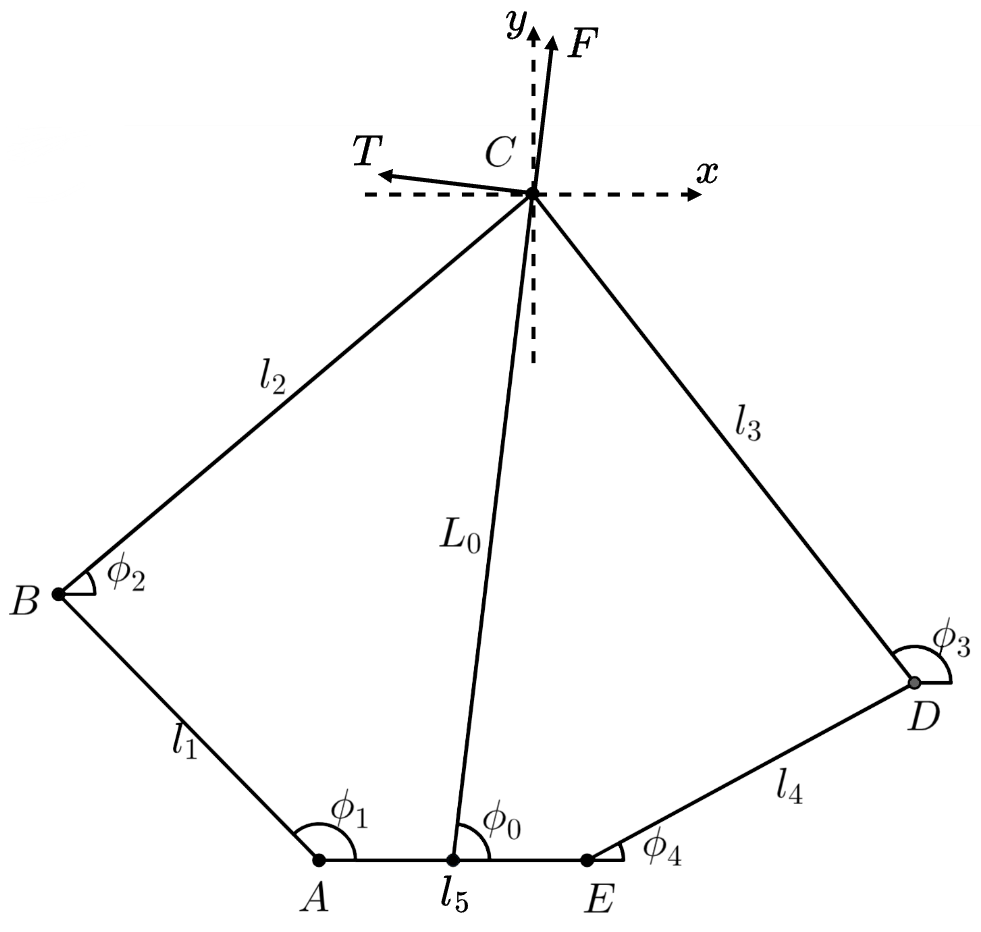

请忽略C点上的坐标。坐标原点应该是在A点而不是C点。

% 本篇根据：《五连杆解算与VMC》写成

clear; clc;
% 运动学正解 （知道关节角度求轮子坐标）

% 参数定义
syms l_1  l_2  l_3  l_4  l_5
syms phi1  phi4
% l_1 = 210;  l_2 = 250; % l_1大腿，l_2小腿
% l_4 = l_1;  l_3 = l_2;
% l_5 = 0;               % l_5同侧关节间距
% phi_1 = (180-18)/180*pi;
% phi_4 = 14 /180*pi;

% 几个坐标的求解
xA = 0;                     yA = 0;
xE = xA + l_5;              yE = 0;
xB = xA + l_1*cos(phi1);   yB = yA + l_1*sin(phi1);
xD = xE + l_1*cos(phi4);   yD = yE + l_1*sin(phi4);

% 中间变量
l_BD = sqrt((xB-xD)*(xB-xD) + (yB-yD)*(yB-yD));
A0 = 2*l_2*(xD - xB);
B0 = 2*l_2*(yD - yB);
C0 = l_BD*l_BD;
phi_2 = 2*atan( (B0 + sqrt(A0*A0 + B0*B0 - C0*C0)) / (A0 + C0) );

% C点直角坐标
xC = xB + l_2*cos(phi_2);
yC = yB + l_2*sin(phi_2);

% 转化为C点极坐标
L_0 = sqrt( (xC - l_5/2)*(xC - l_5/2) + yC*yC );
phi_0 = atan( yC / (xC - l_5/2) )*180/pi;
simplify(L_0);

$$ans = \begin{array}{l} \sqrt{{\left(l_{2}\,\sin\left(\sigma_{1}\right)+l_{1}\,\sin\left(\varphi_{1}\right)\right)}^{2}+{\left(l_{2}\,\cos\left(\sigma_{1}\right)-\frac{l_{5}}{2}+l_{1}\,\cos\left(\varphi_{1}\right)\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=2\,\mathrm{atan}\left(\frac{\sqrt{4\,{l_{2}}^{2}\,\sigma_{3}-{\left(\sigma_{3}+\sigma_{2}\right)}^{2}+4\,{l_{2}}^{2}\,\sigma_{2}}-2\,l_{2}\,\left(l_{1}\,\sin\left(\varphi_{1}\right)-l_{1}\,\sin\left(\varphi_{4}\right)\right)}{\sigma_{3}+\sigma_{2}+2\,l_{2}\,\left(l_{5}-l_{1}\,\cos\left(\varphi_{1}\right)+l_{1}\,\cos\left(\varphi_{4}\right)\right)}\right)\\ \sigma_{2}={\left(l_{5}-l_{1}\,\cos\left(\varphi_{1}\right)+l_{1}\,\cos\left(\varphi_{4}\right)\right)}^{2}\\ \sigma_{3}={\left(l_{1}\,\sin\left(\varphi_{1}\right)-l_{1}\,\sin\left(\varphi_{4}\right)\right)}^{2} \end{array}$$

simplify(phi_0);

% 运动学逆解

% C点极坐标
syms L_0  phi_0
% L_0 = 250;
% phi_0 = 85/180*pi;

% 转化为C点直角坐标
xC = l_5/2 + L_0*cos(phi_0);
yC = L_0*sin(phi_0);

% 中间变量
A0 = 2*xC*l_1;
B0 = 2*yC*l_1;
C0 = xC*xC + yC*yC + l_1*l_1 - l_2*l_2;

phi1 = 2*atan( (B0 + sqrt(A0*A0 + B0*B0 - C0*C0)) / (A0 + C0) );

D0 = 2*(xC - l_5)*l_4;
E0 = 2*yC*l_4;
F0 = (xC-l_5)*(xC-l_5) + yC*yC + l_4*l_4 - l_3*l_3;

phi4 = 2*atan( (E0 - sqrt(D0*D0 + E0*E0 - F0*F0) ) / (D0 + F0) );

phi1 = phi1*180/pi

$$phi1 = \begin{array}{l} \frac{360\,\mathrm{atan}\left(\frac{\sqrt{{l_{1}}^{2}\,{\sigma_{3}}^{2}-{\left(\sigma_{1}+\sigma_{2}+{l_{1}}^{2}-{l_{2}}^{2}\right)}^{2}+4\,{L_{0}}^{2}\,{l_{1}}^{2}\,{\sin\left(\varphi_{0}\right)}^{2}}+2\,L_{0}\,l_{1}\,\sin\left(\varphi_{0}\right)}{\sigma_{1}+l_{1}\,\sigma_{3}+\sigma_{2}+{l_{1}}^{2}-{l_{2}}^{2}}\right)}{\pi }\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{l_{5}}{2}+L_{0}\,\cos\left(\varphi_{0}\right)\right)}^{2}\\ \sigma_{2}={L_{0}}^{2}\,{\sin\left(\varphi_{0}\right)}^{2}\\ \sigma_{3}=l_{5}+2\,L_{0}\,\cos\left(\varphi_{0}\right) \end{array}$$

phi4 = phi4*180/pi

$$phi4 = \begin{array}{l} -\frac{360\,\mathrm{atan}\left(\frac{\sqrt{{l_{4}}^{2}\,{\sigma_{3}}^{2}-{\left(\sigma_{1}+\sigma_{2}-{l_{3}}^{2}+{l_{4}}^{2}\right)}^{2}+4\,{L_{0}}^{2}\,{l_{4}}^{2}\,{\sin\left(\varphi_{0}\right)}^{2}}-2\,L_{0}\,l_{4}\,\sin\left(\varphi_{0}\right)}{\sigma_{1}-l_{4}\,\sigma_{3}+\sigma_{2}-{l_{3}}^{2}+{l_{4}}^{2}}\right)}{\pi }\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{l_{5}}{2}-L_{0}\,\cos\left(\varphi_{0}\right)\right)}^{2}\\ \sigma_{2}={L_{0}}^{2}\,{\sin\left(\varphi_{0}\right)}^{2}\\ \sigma_{3}=l_{5}-2\,L_{0}\,\cos\left(\varphi_{0}\right) \end{array}$$